# MC2: Tracking the embodied dynamics of cognition using computer mouse tracking

Stefan Scherbaum & Martin Schoemann

## Overview

In this MATLAB Live Script, we will have a hands-on look at the embodied dynamics of your own cognition during the [Henik task](https://doi.org/10.3758/BF03202431) which had been implemented and ran in [OpenSesame](https://osdoc.cogsci.nl/3.3/) using the [mousetrap plugin](https://github.com/PascalKieslich/mousetrap-os).

Since we have two separate analysis pipelines both in [R](https://www.r-project.org/) and [Matlab](https://www.mathworks.com/products/matlab.html), we will go through both shared and unique analysis steps. As a rough overview, we will cover:

- Data import

- Geometric processing

- Re-sampling and interpolation

- Data inspection

- Summary measures

- Continuous measure

- Statistical analysis

**Note: Before you run this Script, please add the TCMR Toolbox and the additional functions folder to your Matlab path.**

%% general script settings
clear; clc;
%cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Data import

Our pipeline here in Matlab starts with importing the raw data, combine the single data from each participant, and turning them into a structure that we can easily work with, that is, some of our convenient functions are optimized for.  

datapath = '../dataRaw/';
files = dir([datapath 'subject-*.csv']);
pdata = repmat(struct,1,numel(files));

stimlock_samples=5*1000; %assuming 5s of sampling every 1ms

for p=1:numel(files)
    fname =fullfile(files(p).folder,files(p).name);
    tmp = readtable(fname);
    
    %trial data
    pdata(p).p_num = p;
    pdata(p).t_condition = tmp.Condition';
    pdata(p).t_bignumber = tmp.NumberBig';
    pdata(p).t_smallnumber = tmp.NumberSmall';
    pdata(p).t_bignumberposition = tmp.NumberPositionBig';
    pdata(p).c_correct = logical(tmp.correct');
    pdata(p).c_direction = [];
    
    %convert trial data into vectors were necessary for easier comparison
    %later on
    %Henik congruency: congruent = true=congruent, false = incongruent
    pdata(p).congruent=cellfun(@(x) strcmp(x,'congruent'),pdata(p).t_condition);
    %Was position of big number left: big_left = true=left, false = right
    pdata(p).big_left=cellfun(@(x) strcmp(x,'links'),pdata(p).t_condition);
    
    %mt data (filled with NaNs)
    pdata(p).t_stimlock = cellfun(@(x) str2double(strsplit(x(2:end-1),', ')), tmp.timestamps_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).t_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).t_stimlock, 'UniformOutput', false));
    pdata(p).x_stimlock = cellfun(@(x) str2double(strsplit(x(2:end-1),', ')), tmp.xpos_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).c_direction = cell2mat(cellfun(@(x) sign(x(end)), pdata(p).x_stimlock, 'UniformOutput', false))';
    pdata(p).x_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).x_stimlock, 'UniformOutput', false));
    pdata(p).y_stimlock = cellfun(@(x) str2double(strsplit(x(2:end-1),', ')), tmp.ypos_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).y_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).y_stimlock, 'UniformOutput', false));
end%for

## Geometric Processing

So, the data are imported and available `pdata` in a convenient structure. Now, we look at the cursor trajectories from only one participant in order to learn about:

- how OpenSesame has tracked the cursor position

- what geometric processing steps we need to apply

- to get a feeling for the cursor trajectories

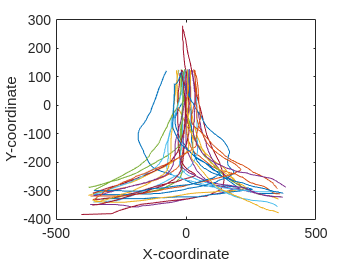

p=1;
figure
plot(pdata(p).x_stimlock',pdata(p).y_stimlock')
ylabel('Y-coordinate');xlabel('X-coordinate');

The plot shows the raw cursor trajectories from the first participant in the struct array, and we can see that the trajectories were tracked in a somewhat twisted way, that is, the coordinate system in OpenSesame was centered in middle of the screen and going upwards toward the response boxes decreased the y-coordinate. We can also see that the trajectories differ in their starting point (i.e., the cursor position in the moment the stimuli were presented) and end point (i.e., the first cursor position in one of the response boxes). And, we see that trajectories going into different response boxes cannot easily be compared as they end in opposite directions. Therefore, we remap the trajectories and align their starting point.

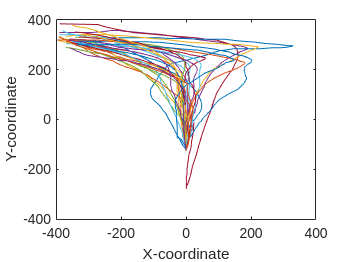

for p=1:numel(pdata)
    % mirror on the horizontal axis
    pdata(p).y_stimlock = pdata(p).y_stimlock*(-1);
    %mirror on the vertical axis, to the left
    pdata(p).x_stimlock = bsxfun(@times, pdata(p).x_stimlock, pdata(p).c_direction'*(-1));
    %align x coordinates to zero as starting point
    pdata(p).x_stimlock = bsxfun(@minus,pdata(p).x_stimlock, pdata(p).x_stimlock(:,1));
    %set timestamps to zero at starting point
    pdata(p).t_stimlock = bsxfun(@minus,pdata(p).t_stimlock, pdata(p).t_stimlock(:,1));
end%for

p=1;
figure
plot(pdata(p).x_stimlock',pdata(p).y_stimlock')
ylabel('Y-coordinate');xlabel('X-coordinate');

## Re-sampling and interpolation

So, the trajectories are in principle comparable but before we can do that in meaningful way, we have to focus on a significant characteristic of such trajectories (well, frankly, that applies to all kinds of time-continuous data), namely, that they are of different lengths. We cannot easily see that characteristic when we plot the trajectories on the x/y-plane, but when we plot both `x_stimlock` and `y_stimlock` as a function of `t_stimlock`.

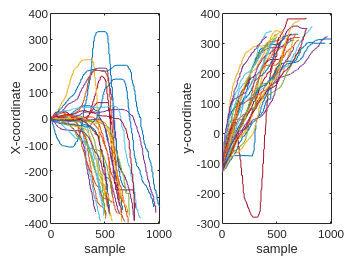

p=1;
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile
plot(pdata(p).t_stimlock',pdata(p).x_stimlock')
ylabel('X-coordinate');xlabel('sample')
nexttile
plot(pdata(p).t_stimlock',pdata(p).y_stimlock')
ylabel('y-coordinate');xlabel('sample')

Different lengths can be due to different sampling frequencies, different times participants took to reach a response box (i.e., because they took short/longer paths or moved the cursor faster/slower), or both. Both aspects can be treated by re-sampling and interpolation in such a way that each trajectory is represented by an equal number of points. Time-normalization interpolates trajectories such that they are represented by exactly the same number of temporally equidistant data points, and the number is typically chosen to be 101 (`calcTrajectories()`). Length-normalization interpolates the trajectory into the same number of spatially equidistant data points (not implemented). Another way of representing each trajectory by an equal number of data points is to interpolate the trajectories such that timestamps are equidistant from each other and to fill up each trajectory with its own last data point times the number of data points that are needed to obtain the same length as the longest trajectory in the data (`normLength()`); thus the longest trajectory in the data determines the length of all other trajectories and is hence not filled up.

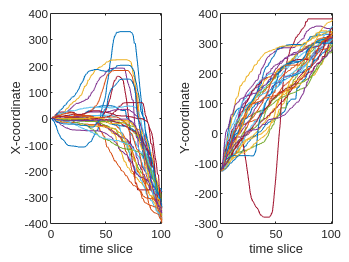

for p=1:numel(pdata)
    [pdata(p).x_warp,pdata(p).y_warp,pdata(p).angle_warp,pdata(p).velocity_warp,...
     pdata(p).dev_warp]=calcTrajectories(pdata(p).x_stimlock,pdata(p).y_stimlock,101,1000);
end%for

p=1;
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile
plot(1:101,pdata(p).x_warp')
ylabel('X-coordinate');xlabel('time slice')
nexttile
plot(1:101,pdata(p).y_warp')
ylabel('Y-coordinate');xlabel('time slice')

## Data inspection

So, after preprocessing, we need to better understand our data and see whether there are any quirks hidden in it.

### Heat maps 

Heat maps are a great way get an overview of the data. A simple way to get a heat map is to pool all trials from all subjects and plot them as a heat map. We use a function that works like a 2D histogram: It bins the data into coordinate bins and then plots frequencies color coded as a 2D map.

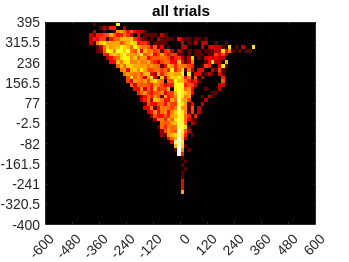

%pool all trials
allx=vertcat(pdata.x_warp);
ally=vertcat(pdata.y_warp);


figure;
colormap('hot')
imagep2d(allx,ally,-600:15:600,-400:15:400,[],[],1);
title('all trials')

Since we have two conditions of congruency (congruent vs incongruent) in the task, which might affect the movements decisively, it does not hurt to get an impression of the heat maps split up by condition.

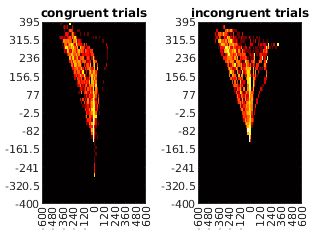

allcong=horzcat(pdata.congruent)';

%plot heatmaps by condition
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
colormap('hot')
nexttile
imagep2d(allx(allcong,:),ally(allcong,:),-600:15:600,-400:15:400,[],[],1);
title('congruent trials')
nexttile
imagep2d(allx(~allcong,:),ally(~allcong,:),-600:15:600,-400:15:400,[],[],1);
title('incongruent trials')

### Reversals

A typical problem in mouse-tracking studies is that subjects move the mouse backwards to gain some additional space for their decision. This can be checked by counting the trials in which the mouse moved backwards on the y-axis at any time, captured here in the variable `returns `for each subject . Another problem is that subjects might stop their movement, which logically prevents any cognition to leak into the non-existent movement. Ideally, all trials would show a movement of a constant speed which would result in a straight movement on the y-axis (though in reality, we know that subjects regularly slow down a bit during stimulus processing). Hence, we can correlate the real movement on the y-axis with a constant movement on the y-axis and see whether any trials strongly deviate from the constant movement, captured in the variable `cont` for each subject. 

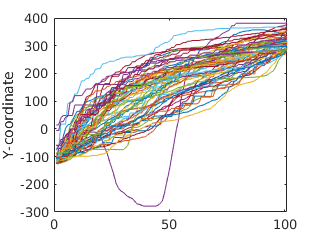

figure
plot(1:101,ally');
ylabel('Y-coordinate')

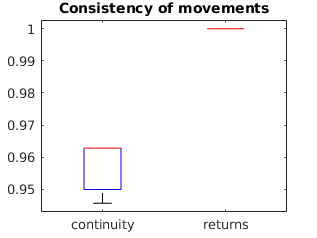


%check movement quality: how straight is each movement and how many movements show returns (y direction should be increasing constantly (=1)
for p=1:numel(pdata)
    [cont(p,:),returns(p,:)]=calcMovementContinuity(pdata(p).y_warp,1);
end

figure
boxplot([cont,returns])
set(gca,'XTick',1:2); set(gca,'XTickLabels',{'continuity','returns'})
title('Consistency of movements')

### Main Effect in trajectories

Now we can look qualitatively at the main effects of movements between the congruent and the incongruent condition. Per subject, we take the mean of all movements of one condition. Note, that we only include trials that were solved correctly .

Lets first do this on the X/Y-plane

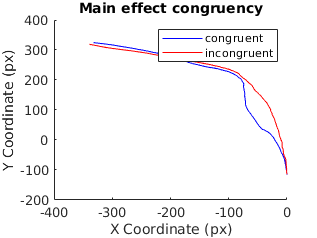

%aggregate data
clear cx ix
for p=1:length(pdata)
    valid=pdata(p).c_correct;
    cx(p,:)=nanmean(pdata(p).x_warp(valid & pdata(p).congruent,:));
    ix(p,:)=nanmean(pdata(p).x_warp(valid & ~pdata(p).congruent,:));
    cy(p,:)=nanmean(pdata(p).y_warp(valid & pdata(p).congruent,:));
    iy(p,:)=nanmean(pdata(p).y_warp(valid & ~pdata(p).congruent,:));

end

figure; hold on
plot(mean(cx),mean(cy),'b');
plot(mean(ix),mean(iy),'r');
legend('congruent','incongruent');xlabel('X Coordinate (px)');ylabel('Y Coordinate (px)');
title('Main effect congruency')

The effect is also clearly visible when we only look on the effects on the X-axis, which also allows us to look at the time-course and to indicate the variance across subjects by drawing shaded error areas around the mean trajectories.

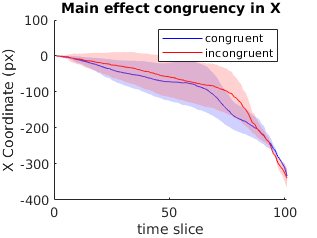

figure;hold on
errorArea(mean(cx),ste(cx),'b');
errorArea(mean(ix),ste(ix),'r');
legend('congruent','incongruent');xlabel('time slice');ylabel('X Coordinate (px)');
title('Main effect congruency in X')

If we want a time-course for a measure that integrates X- and Y-movement, we can use the angle. Since this is a differential measure, it is a bit noisier than X-coordinates.

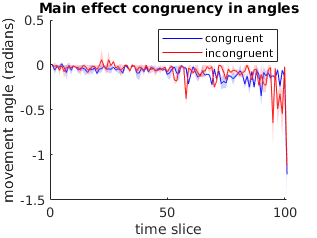

%aggregate data
clear ca ia
for p=1:length(pdata)
    valid=pdata(p).c_correct;
    ca(p,:)=nanmean(pdata(p).angle_warp(valid & pdata(p).congruent,:));
    ia(p,:)=nanmean(pdata(p).angle_warp(valid & ~pdata(p).congruent,:));
end
figure;hold on
errorArea(mean(ca),ste(ca),'b');
errorArea(mean(ia),ste(ia),'r');
legend('congruent','incongruent');xlabel('time slice');ylabel('movement angle (radians)');
title('Main effect congruency in angles')

## Summary measures

So, now we a rather complete picture about how the data look like, and we have a qualitative idea about the effects in the data. However, in science, we are usually asked to put the observed qualities into quantities. One way to do that is to use summary measures (or trajectory indices) that summarize characteristics of the trajectories into single values per trial. Fortunately (or unfortunately), there exist a plethora of such measures focusing on one of three characteristics: curvature, complexity, or time. Here, we focus on curvature by examining the maximum absolute deviation (MAD) and area under the curve (AUC).

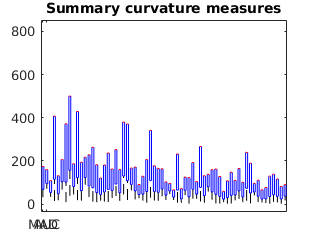

for p=1:numel(pdata)
    [pdata(p).auc,pdata(p).mad]=calcStatic(pdata(p).x_warp, pdata(p).y_warp);
end%for

% figure

% boxplot([mad, auc])
% set(gca,'XTick',1:2); set(gca,'XTickLabels',{'MAD','AUC'})
% title('Summary curvature measures')

## Advanced measures

### TCMR

A rather advanced idea is to investigate the influence of certain (experimental) factors on the trajectory over time. We can do that by applying the Time Continuous Multiple Regression (TCMR) in which we predict the movement angle on every time step based on the congruency condition.

clear betas
figure
for p=1:length(pdata)  
    valid=pdata(p).c_correct;

    %calc regressors of each participant
    congs=-pdata(p).congruent';%congruency
    
    %concatenate regressors and normalize each to [-1,1]
    regressors=normalizeRegressors([congs]);    
    %define data for TCMR
    regdata=pdata(p).x_warp;
    
    %catch plotted information from TCMR
    subplots(length(pdata),p); 
    
    betas(:,:,p)=TCMRegression(regdata(valid,:),regressors(valid,:),1);    
end

%% determine some process parameters directly from data
%peaks=findStatPeaks(betas,'jackknife');
segments=findStatSegments(betas,0.05);


%% plot results summary for TCMR and fitting results
figure;clear s
plotRegression(betas);
plotSegmentLines(segments,10);
%plotPeaks(peaks,0.05);
xlabel('time slice');ylabel('\beta weight')
title('TCMR results')
legend('response bias','interference')

## Possible exercises

**Investigate the influence of another experimental factor!** For instance, other factors might be the difference between the two numbers, or the congruency of the previous trial.

TODO